## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 14 - Displacement Controlled Method**

**14.1 Snap-Through Behaviors in a Bistable Truss:**

Here, to introduce the displacement controlled method, let's take a look at a classical bistable structure formed with two bar and three nodes (following figure). When pressing this structure downward, it will start deforming and suddenly snap to the other side. Let's model this system with the package. 

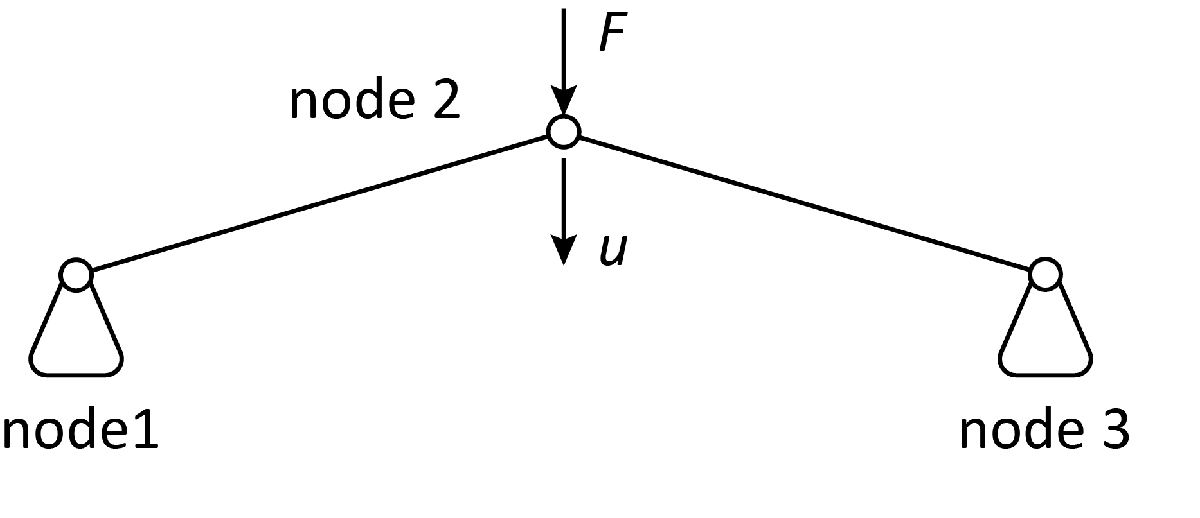

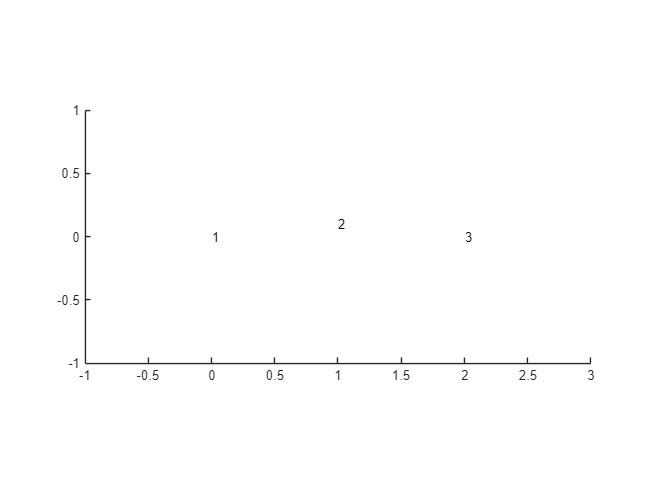

%% Initialize the truss
% Define the nodes

barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;

% Create the truss Assembly
assembly=Assembly_Truss;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0 0 0; 
                      1 0 0.1;
                      2 0 0; 
                      ];

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;

% We will plot for the truss assembly
plots.displayRange=[-1;3;-1;1;-1;1]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

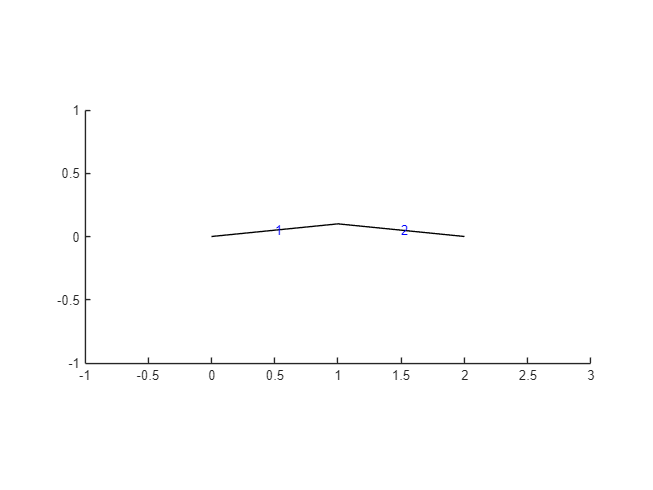


% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,2;
                 2,3;]; % 

% Define the area of the bars
bar.A_vec=barA*ones(2,1);

% Define the Young's modulus of the bars
bar.E_vec=barE*ones(2,1);

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

Cool, we have the structure defined now. Next, we should first try to simulate the behavior of this system using the nonlinear Newton-Raphson solver we previously learned. We will plot the Force-Displacement curve and see what happens. 

% Solver Initialization
nr=Solver_NR_Loading;
nr.assembly=assembly;

% node 1 and node 3 are fixed
% node 2 is fixed in y direction for 2D problem
nr.supp=[1 1 1 1;
         2 0 1 0;
         3 1 1 1];

% Push downward at node 2
nr.load=[2 0 0 -10];
nr.increStep=50;

% Solve the deformation
Uhis=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 2.537594e-03
    Iteration = 2, R = 1.028448e-04
    Iteration = 3, R = 1.819914e-07
Icrement = 2
    Iteration = 1, R = 2.760331e-03
    Iteration = 2, R = 1.177857e-04
    Iteration = 3, R = 1.336653e-06
Icrement = 3
    Iteration = 1, R = 3.043813e-03
    Iteration = 2, R = 1.552921e-04
    Iteration = 3, R = 1.091309e-05
    Iteration = 4, R = 1.838569e-07
Icrement = 4
    Iteration = 1, R = 3.420682e-03
    Iteration = 2, R = 1.890704e-04
    Iteration = 3, R = 3.379118e-06
Icrement = 5
    Iteration = 1, R = 3.955218e-03
    Iteration = 2, R = 2.522627e-04
    Iteration = 3, R = 1.280649e-05
    Iteration = 4, R = 3.669366e-07
Icrement = 6
    Iteration = 1, R = 4.793569e-03
    Iteration = 2, R = 4.183868e-04
    Iteration = 3, R = 2.949379e-05
    Iteration = 4, R = 6.330692e-06
Icrement = 7
    Iteration = 1, R = 5.619435e-03
    Iteration = 2, R = 2.016939e-03
    Iteration = 3, R = 4.412511e-05
    Iteration = 4, R = 

You will see that the structure will suddenly snap to the other side. More specifically, this happens at increment 8. We can see that increment 8 requires much more iterations to converge than other steps. If we plot the GIF, we will see that the snap happens suddenly. 

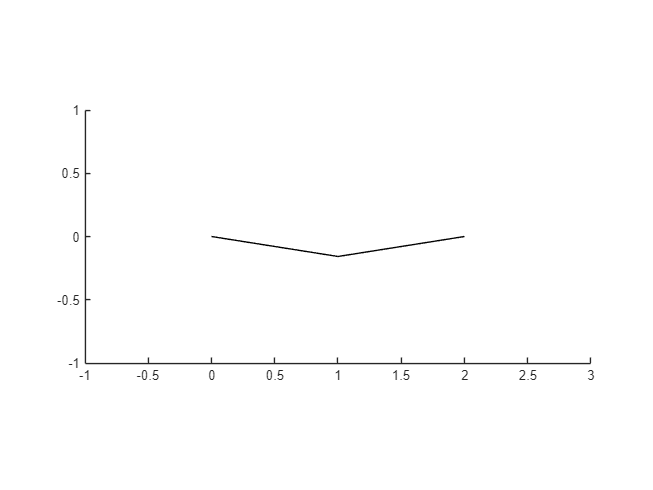

% plot the deformation process
plots.fileName='NR-animation.gif';
plots.Plot_Deformed_His(Uhis(1:5:end,:,:));

Now, let's try to look at the force-displacement curve. 

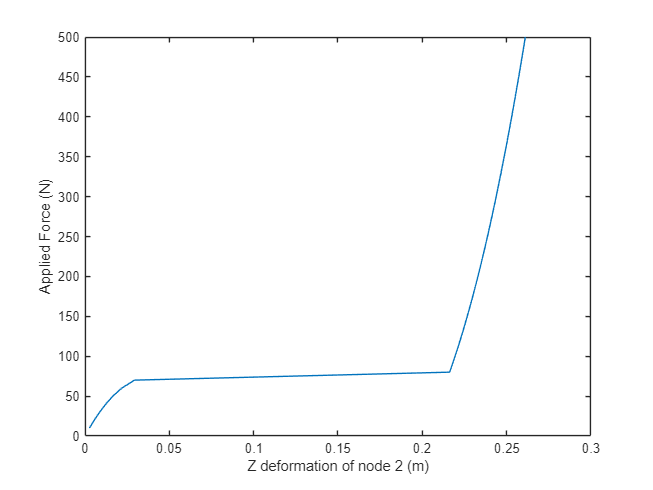

% Z direction motion of node 2
Unode=Uhis(:,2,3);

% nodal force can be found as the following
Fhis=((1:50)*10)';

% plot the relationship
plot(-Unode,Fhis)
xlabel('Z deformation of node 2 (m)') 
ylabel('Applied Force (N)') 

Once the force reached around 70 N, the displacement suddenly jumped from 0.03 to 0.21 m. In reality, this indicates that a dynamic process will happen and we can no longer neglect the mass in the system (it will contribute to the system equilibrium). 

**14.2 Introducing Displacement-Controlled Method:**

The bistable truss system actualy has a very complex nolinear mechanic response in the deformation process. This is actually not captured during by the Newton-Raphson solver, because the Newton-Raphson can only increase the applied force. However, the system can actually maintain equilibrium if we allow the force to drop during the snap through. To capture that, we need the displacement controlled method. To understand how displacement controlled solver works, we shall revisit the Newton-Raphson solver first. The bottom left figure shows a Newton-Raphson solver tracing the equilibrium curve of a structure with two degree of freedoms u1 and u2. In the bottom left figure, the equilibrium curve is the dark line and it goes up and down in the F-axis, meaning that the applied force needs to increase, decrease, and increase again to follow the path exactly. When the Newton-Raphson search for the next equilibibrium points, it will increase the applied load (moving from the blue plane to the red plane). This means that the Newton-Rapshon solver will consistently miss any nonlinear equilibrium path with decreasing forces. 

On the other hand, the displacement-controlled method can address the issue by using an alternative serach plane (it is also called constraints in literature). For example, if we specify that u2 will increase a target amount per increment, we create the search plane shown in the bottom right figure. This approach will enable us to find those equilibrium points with decreasing forces on the path. 

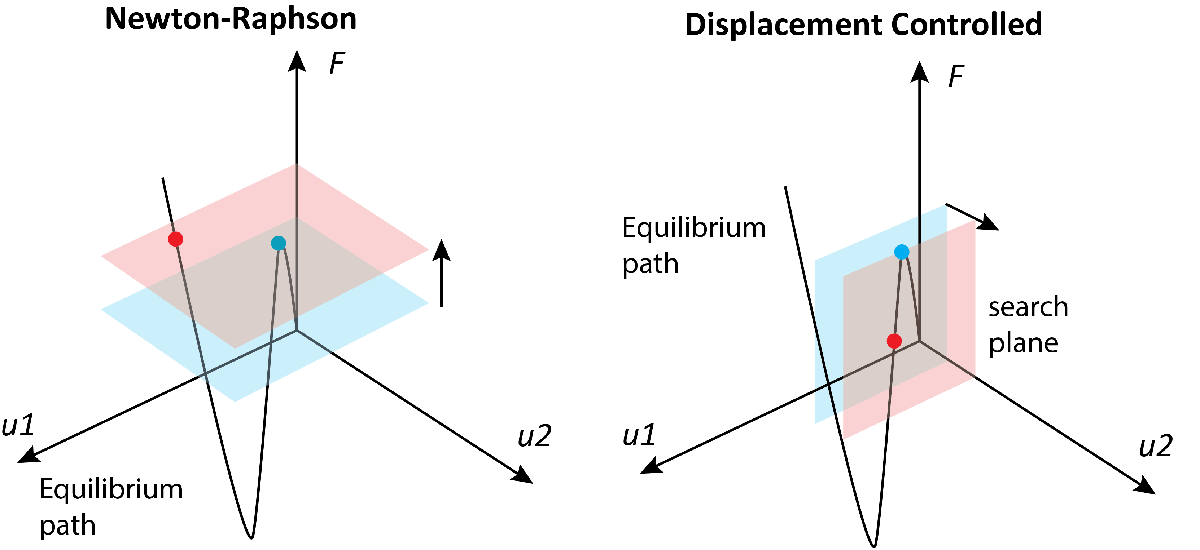

Please pay attention that the displacement-controlled method is NOT tracing equilibrium with support deformation. The following figure shows the difference. Tracing the nonlinear equilibrium path with support deformation is more restrictive on the deformation search space than using the displacement-controlled solver. For instance, in the case of the upper figure, the node 3 is forced to only move downward without the ability to account for lateral motions. 

On the other hand, the displacement controlled solver enables less restrictive search space. Allowing us to find the nonlinear equilibrium path under complex loading conditions. For example, multiple loads can be applied on the same arch and the buckling shape can change depending on the loading conditions. These deformations cannot be solved by prescirbing a support deformation and trace the equilibrium with Newton-Raphson solver. 

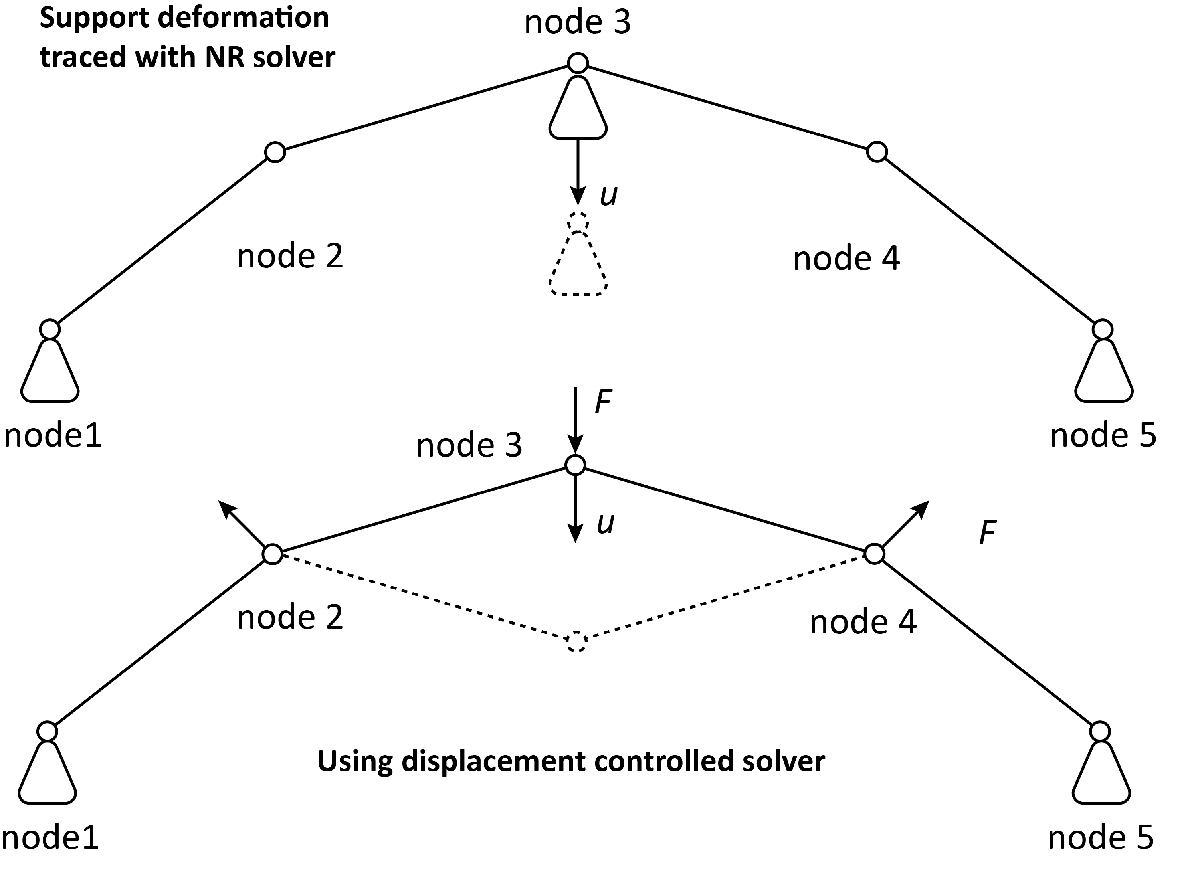

**14.3 Displacement-Controlled Method Formulation:**

In an increment step, assuming that the structure has a configuration of $\mathit{\mathbf{x}}$. Then the stiffness and the internal force of the structure is $\mathit{\mathbf{K}}\left(\mathit{\mathbf{x}}\right)$ and ${\mathit{\mathbf{f}}}_{\mathit{\mathbf{i}}\;} \left(\mathit{\mathbf{x}}\right)$. Assume that we want to trace the equilibrium of the structure under the applied load $\lambda \;\;{\mathit{\mathbf{f}}}_{\mathit{\mathbf{a}}\;}$. Here, the applied load is represented using a $\lambda \;$ factor and a load vector ${\mathit{\mathbf{f}}}_{\mathit{\mathbf{a}}\;}$. Within every interation, the change in the $\lambda \;$is:


$$d\lambda =\frac{-{\mathit{\mathbf{u}}}_{\mathit{\mathbf{r}}\;} \left(n\right)}{u_p \;\left(n\right)}$$
 


$${\mathit{\mathbf{u}}}_{\mathit{\mathbf{p}}} ={\mathit{\mathbf{K}}\left(\mathit{\mathbf{x}}\right)}^{-1} \;{\mathit{\mathbf{f}}}_{\mathit{\mathbf{a}}\;}$$



$${\mathit{\mathbf{u}}}_{\mathit{\mathbf{r}}} ={\mathit{\mathbf{K}}\left(\mathit{\mathbf{x}}\right)}^{-1} \cdot \left\lbrack \lambda \;{\mathit{\mathbf{f}}}_{\mathit{\mathbf{a}}} -{\mathit{\mathbf{f}}}_{\mathit{\mathbf{i}}\;} \left(\mathit{\mathbf{x}}\right)\right\rbrack$$


Here, $n$ is the direction we select as the tracking deformation. The change in the deformation is:


$$du=d\lambda \cdot u_p +u_r$$


Now, let's try to see how we can achieve this incremental-iterative process. To get started, we need to initialize some of these parameters:

% Current deformation and deformation history
U=zeros(3,3);
Uhis=zeros(150,3,3);

% Lambda is used to reflect the applied force
% lambdaHis is used to store the force history
lambda=1;
lambdaHis=zeros(150,1);
% lambda bar is a term used to modify the first step
lambdaBar=1;

% load vector. 
% a downward 10 N force is applied at node 2 in the z-direction
loadVec=[0 0 0 0 0 -10 0 0 0]';
selectedReferenceNodeNum=6;

% current applied load vector
pload=loadVec*lambda;

% support condition
supp=[1 1 1 1;
      2 0 1 0;
      3 1 1 1;];


After initializing the variables, we can proceed to set up the incremental-iterative loop. Please note that the code needs to implement the first interation differently, because we need to make sure that the deformation is moving in the positive direction:

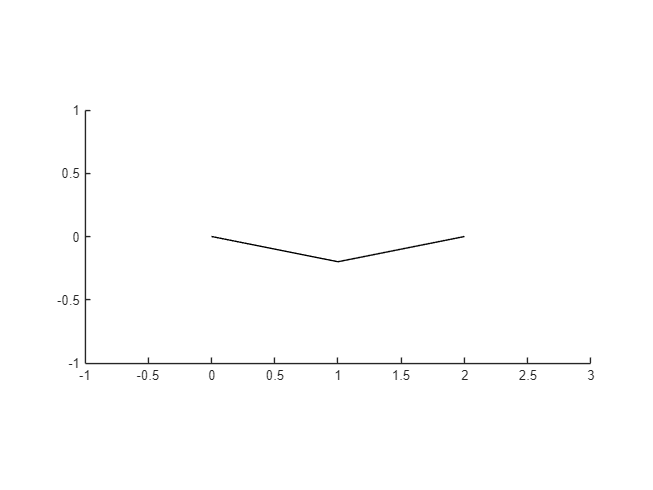

% We will perform 150 increment of loading
for i=1:150

    step=1;     

    % find the internal force and stiffness of system
    [T,K]=assembly.Solve_FK(U);

    % calculate the unbalanced force
    unbalance=lambda*loadVec-T; 

    [K,unbalance]=Mod_K_For_Supp(K,supp,unbalance);
    K=sparse(K);                         
          
    % We want to make sure that we are always moving in the positive
    % direction This code is added to do that.
    up1(:,i)=K\loadVec; 
    if norm(up1)==0
        sig=1;
    else
        if i==1
            sig=1;
        else
            sig=sign(up1(:,i-1)'*up1(:,i))*sig;        
        end
    end
    
    % Sig is used to make sure we are moving in the positive direction
    dLambda=sig*lambdaBar;

    lambda=lambda+dLambda;
    pload=pload+dLambda*loadVec;    

    dUtemp=dLambda*up1(:,i);

    for j=1:3
        U((j),:)=U((j),:)+dUtemp(3*j-2:3*j)';
    end  
    R=norm(dUtemp);    
    step=step+1;       

    while and(step<30,R>10^-7)

        % find the internal force and stiffness of system
        [T,K]=assembly.Solve_FK(U);

        % calculate the unbalanced force
        unbalance=lambda*loadVec-T; 

        [K,unbalance]=Mod_K_For_Supp(K,supp,unbalance);
        K=sparse(K);  

        % These part of the code is implementing the equations for
        % displacement controlled method
        up=K\loadVec;
        ur=K\unbalance;

        % find the force step for lambda
        dLambda=-ur(selectedReferenceNodeNum)/up(selectedReferenceNodeNum);

        lambda=lambda+dLambda;
        pload=pload+dLambda*loadVec;
        
        % find the dispalcement step for U
        dUtemp=dLambda*up+ur;
        for j=1:3
            U((j),:)=U((j),:)+dUtemp(3*j-2:3*j)';
        end

        R=norm(dUtemp);     
        step=step+1;  
    end 

    % Store the found equilibrium
    Uhis(i,:,:)=U;
    lambdaHis(i)=lambda;

end    
% plot the deformation process
plots.fileName='DC-animation.gif';
plots.Plot_Deformed_His(Uhis(1:10:end,:,:));

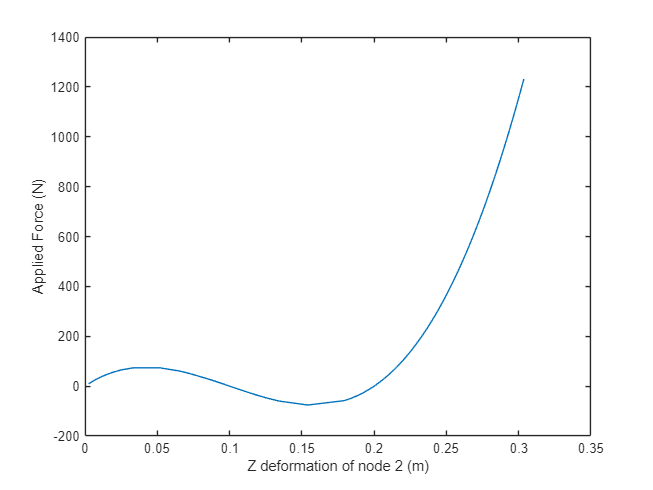

% Z direction motion of node 2
Unode=Uhis(:,2,3);

% nodal force can be found as the following
Fhis=(lambdaHis*10);

% plot the relationship
plot(-Unode,Fhis)
xlabel('Z deformation of node 2 (m)') 
ylabel('Applied Force (N)') 

As we can see, now the simulation can track the full nonlinear equilibrium path without skipping the unloading section where the applied forces need to drop. In the simulation package, the class "Solver_DC" is used to implement the displacement controlled method. 

**14.4 References and Related Class**

Again the best paper for learning more about different nonlinear solver is this paper by Leon et. al.

[https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes](https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes)

In addition to this, other related classes for this chapter is: **Nonlinear Structural Analysis **